# Setting up data and visualisation

Before starting the tutorial make sure you increase the java heap memory to the maximum avaialble space, otherwise MATLAB will crash many times. Refer to the below image for setting up. It can be found under Home button -> Preferences.

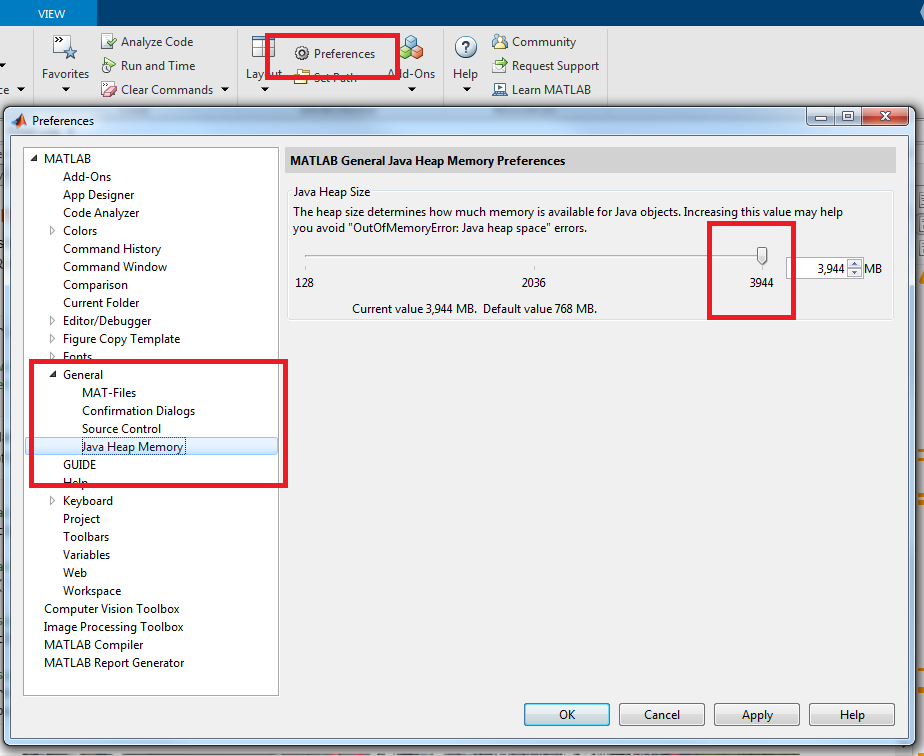

% download data and copy in the present working directory
clear;clc; close all;% clear workspace and command window

if ~exist('FinalCode.zip','file')
    disp('Downloading file (658 MB)...');
    URL = 'https://rmit.figshare.com/ndownloader/files/24753887';
    websave('FinalCode.zip',URL);
else
    disp('Zip file exists, unzipping')
end

Zip file exists, unzipping


unzip('FinalCode.zip')
disp('Unzipped files')

Unzipped files


addpath('FinalCode/') 
addpath('FinalCode/SupportingFunctions/') 


### Visualise PKLot dataset

PKLot dataset contains 12000+ CCTV images and 695,000+ segmented parking slot images. The occupancy was manually generated. For the scope of the tutorial, we sampled 389 CCTV images and only the occupied slots.

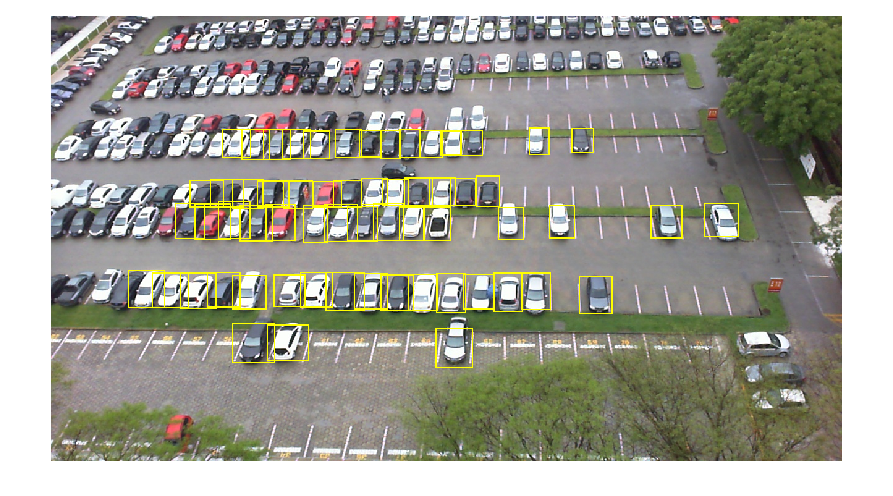

% load one image
PKLotImage = imread('FinalCode\PKLotSampled\2012-10-11_07_56_23.jpg'); 

% load ground truth of occupied images of PKLot
load('GroundTruthPKLotParking.mat')

% Insert annotation of occupied parking spaces in the image
PKLotImage = insertShape(PKLotImage,'rectangle',vehicleDataset.vehicle{1,1},...
    'LineWidth', 2);

% Visualise PKLot parking
figure
imshow(PKLotImage) % Note that only a part of the occupied cars are annotated.

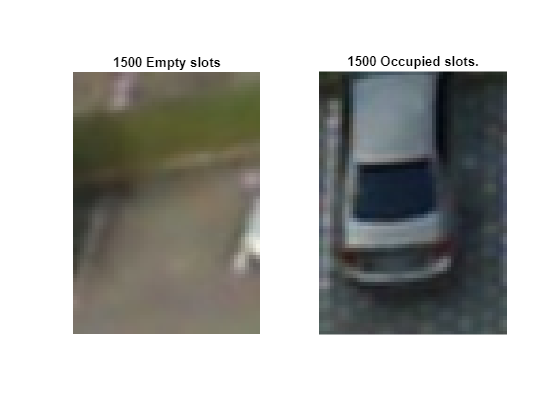

% Visualise the segmented images of PKLot dataset (We sampled 1500 occupied and 1500 Empty spaces)
PKLotEmpty = imresize(imread(...
    'FinalCode\PKLotSegmentedSampled\Empty\2012-09-11_15_45_57#004.jpg'), [70 50]);
PKLotOccupied = imresize(imread(...
    'FinalCode\PKLotSegmentedSampled\Occupied\2012-09-11_15_36_32#100.jpg'), [70 50]);
figure
subplot(1,2,1)
imshow(PKLotEmpty);
title ('1500 Empty slots')
subplot(1,2,2)
imshow(PKLotOccupied);
title ('1500 Occupied slots.')

### Visualise Barry street data

Visualise Barry street (100 images with 28 parking lots). This is our test data, and we want to identify the parking slots automatically, and subsequently perform occupancy detection. Ground truth and parking slot annotations are for evaluation purpose.

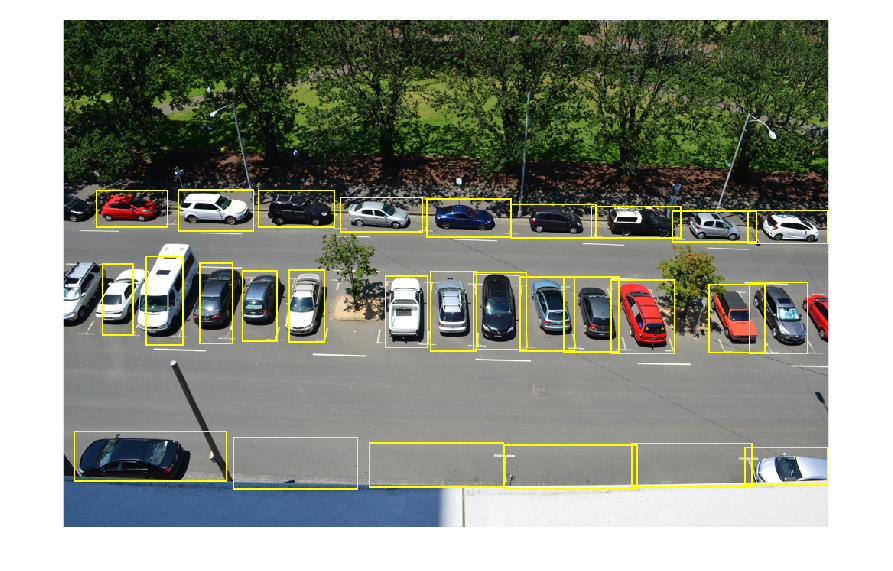

% Load one image.
BarryStreetImage = imread('FinalCode\BarryStreetData\DSC_0455.JPG');

% load the parking slot markings and occupancy
load('GroundTruthBarryStreet.mat');

% Visualise Barry Street
figure
BarryStreetImageAnn = insertShape(BarryStreetImage,'rectangle',ParkingSlots,...
    'LineWidth', 2);
imshow(BarryStreetImageAnn);

This concludes the dataset visualisation.

# Turorial 1 - Fine-tuning a pre-trained network as car detector

#### Training must have GPU, but testing can be performed with CPU

The following snippet will load a pre-trained Resnet50 CNN and will fine-tune with PKLot dataset. Subsequently, the fine-tuned nwtwork will be tested with Barry Street dataset. Learning plots and evaluation of the results will be performed as well.

clear;clc;close all;

### Fine-tune Resnet50 network with PKLot dataset

Please note that training online needs a GPU. For convinience we provide the trained model that can be tested on CPU. Set the option in the following line to true to perform the training online or to load the trained model.

TrainOnline = false;

if (TrainOnline == true)

% load the pre-trained Resnet50 model that we will fine-tune using PKLot
% segmented images.
load('Resnet50FeatureExtractor.mat');

% Create an image database to store the images which will be used to
% fine-tune the CNN
imds = imageDatastore([pwd '\FinalCode\PKLotSegmentedSampled\'], 'IncludeSubfolders',true,...
    'LabelSource','foldernames');

% Randomly split the trainig set (70%) and the validation set (30%)
[imdsTrain,imdsValidation] = splitEachLabel(imds,0.7,'randomized');

numClasses = 2; % Number of classes: Occupied and Empty

% replace the classification and the fully connected layers of the
% pre-trained model with new ones
lgraph = layerGraph(net);
% find classification and FC layers
[learnableLayer,classLayer] = findLayersToReplace(lgraph);
 % create a new FC layer   
newLearnableLayer = fullyConnectedLayer(numClasses,'Name','new_fc');
% replace fully connected layer
lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);
% new classification layer
newClassLayer = classificationLayer('Name','new_classoutput'); 
% replace classification layer
lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);
layers = lgraph.Layers; % define layers
connections = lgraph.Connections; % extract connections of the new graph
lgraph = createLgraphUsingConnections(layers,connections); % connect graph and new layers

% define input size of the network and the scale range for augmentation
inputSize = net.Layers(1).InputSize;
scaleRange = [0.9 1.1];

% Image augmentor to increase training images by rotating and reflecting
% the original images
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandYReflection',true, ...
    'RandXScale',scaleRange, ...
    'RandYScale',scaleRange);

% define augmented training dataset
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain, ...
    'DataAugmentation',imageAugmenter);

% define augmented validation dataset
augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);

% define validation frequency 
valFrequency = 3;
options = trainingOptions('sgdm', ...
    'MiniBatchSize',10, ...
    'MaxEpochs',20, ...
    'InitialLearnRate',5e-3, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',valFrequency, ...
	'LearnRateDropFactor', 0.5, ...
    'LearnRateDropPeriod', 5, ...
    'Verbose',true);

% Train the new model
[net,traininfo]  = trainNetwork(augimdsTrain,lgraph,options);

else
    load('TrainedDetectorResnet50.mat');
    load('trainingInfoResnet50.mat');
    disp('Trained detector and training log loaded')
end

Trained detector and training log loaded


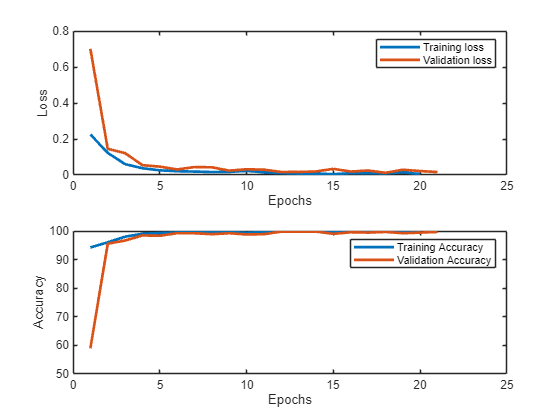

% Plot the traing curves
% pre-process the raw training data
count=1;
for n=1:210:4200
   TrainLoss(count) = mean(traininfo.TrainingLoss(n:n+209));
   TrainAccuracy(count) = mean(traininfo.TrainingAccuracy(n:n+209));
   count=count+1;
end
ValidationLoss =rmmissing(traininfo.ValidationLoss);
ValidationAccuracy = rmmissing(traininfo.ValidationAccuracy);
figure
subplot(2,1,1)
plot(TrainLoss, 'lineWidth', 2);
hold on
plot (ValidationLoss, 'lineWidth', 2)
legend('Training loss', 'Validation loss')
xlabel('Epochs'); ylabel('Loss');
subplot(2,1,2)
plot(TrainAccuracy, 'lineWidth', 2);
hold on
plot (ValidationAccuracy, 'lineWidth', 2)
legend('Training Accuracy', 'Validation Accuracy')
xlabel('Epochs'); ylabel('Accuracy');

### Test the fine-tuned network with Barry street dataset

% This step might take 5 minutes on CPU or a couple of seconds on a GPU.
% For convinience we have provided the output files. Change the following
% line to run the process online
RunOnline = false;

% set the directory containing the Barry street dataset
imageName = dir(fullfile(pwd,'FinalCode\BarryStreetData\', '*.JPG'));
imageName = {imageName.name}';

% load the ground truth of Barry street that contains the occupancy status
% and delination of each parking slots.
load('GroundTruthBarryStreet.mat')
% Fetch the input size of the CNN for resizing the input image
inputSize = net.Layers(1).InputSize;

Dot indexing is not supported for variables of this type.


% Predict the occupancy status using the fine-tuned CNN.
% This step might take 5 minutes on CPU or a couple of seconds on a GPU.
% For convinience we have provided the output files. Change the following
% line to run the process online

if RunOnline == true
    tic
    count =1;
    for n=1:length(imageName)
        BarryStreetImage = imread (fullfile (...
            pwd,'FinalCode\BarryStreetData\', imageName{n}));
        for m=1:length(Occupancy(:,1))
            cropImage{count} = imcrop(BarryStreetImage, ParkingSlots(m,:));
            if Occupancy (m,n)==1
                AnnotationTable{count} = 'Occupied';
            else
                AnnotationTable{count} = 'Empty';
            end
        imdsIm = imresize(cropImage{count}, inputSize(1:2));
        [YPred(count),probs(count,:)] = classify(net,imdsIm);
        count=count+1;
        end
    end
    toc
else 
    load('BarryStreetTestResults.mat');
    disp('Test results loaded');
end

% evaluate the accuracy on the test data
testAccuracy = mean(YPred == AnnotationTable);
fprintf('The test accuracy of the classifier %f %%.\n',testAccuracy*100);

% plot the confusion matrix
plotconfusion (categorical(AnnotationTable), YPred);

### Visualise some of the wrong classifications

% we can visualise some wrongly classified slots
WrongSlots = find(YPred ~= AnnotationTable);
figure
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);
for n=1:length(WrongSlots)
    subplot(6,4,n);
    imshow(cropImage{WrongSlots(n)});
    str = [char(YPred(WrongSlots(n))) ' Score: ' num2str(max(probs(WrongSlots(n),:)))];
    title(str);
end

### Visualise the occupancy

figure
AnnotatedImage = imread("FinalCode\BarryStreetData\DSC_0040.JPG");
emptySlots = 0;
occupiedSlots =0;
for n=1:28
    if YPred(n) == "Empty"
       AnnotatedImage =  insertShape(AnnotatedImage,'FilledRectangle',...
    ParkingSlots(n,:),'LineWidth', 1, 'Color', "green", 'Opacity', 0.4);
    emptySlots = emptySlots + 1;
    else
       AnnotatedImage =  insertShape(AnnotatedImage,'FilledRectangle',...
    ParkingSlots(n,:),'LineWidth', 1, 'color', "red", 'Opacity', 0.4);
    occupiedSlots = occupiedSlots + 1;
    end
end
imshow(AnnotatedImage)
text (100, 50,['Occupied slots: ' num2str(occupiedSlots)],'Color', 'red','FontSize',20);
text (100, 100,['Empty slots: ' num2str(emptySlots)],'Color', 'green','FontSize',20); 

This concludes Tutorial 1.

# Tutorial 2 - Automatic parking slot recognition

#### Training must have GPU, but test can be performed on CPU.

The following snipped will fine-tuned a Faster-RCNN vehicle detector with PKLot dataset (or will download a fine-tuned network), and will detect parking slots in Barry street parking area. Spatio-temporal data of consequtive frames and statistics of the detected parking slots will be used to improve delination of the parking spaces.

clear;clc;close all;

### Fine-tune the pre-trained Faster RCNN model with PKLot data

For fine-tuning the model, GPU must be used, and it took appoximately 5 hours for finish the training. It is not possible to train it on CPU. Therefore, for the scope of the tutorial, we provide a trained model that can be used as is for the detection.

Change the following line for turning training off or on. When training is turned on, it will train and save the model, and its training information. .


train = false;

if train == true

Load a pre-trained Faster RCNN detector (CNN model) to detect cars. The following line will load a pre-trained Faster RCNN detector that was trained to detect cars in highway from a camera mounted on a vehicle. The loaded detector performs well to detect vehicles on highway, however, its performence to detect cars in CCTV images that has been taken from an oblique view is questionable. Therefore, in the next steps, we will fine-tune the detector with PKLot dataset to improve the vehicle detection rate. 

    load('fasterRCNNResNet50Pretrained.mat')
    disp('Pre-trained model loaded')
    detector = layerGraph(detector.Network)
    options = trainingOptions('sgdm', ...
        'MiniBatchSize', 1, ...
        'InitialLearnRate', 2e-3, ...
        'MaxEpochs', 25, ... % Ideally till the loss curve is flat
        'Verbose', true);
    
    % Train an R-CNN object detector. This will take several minutes.    
    load('GroundTruthPKLotParking.mat')
    [rcnn,traininfo] = trainFasterRCNNObjectDetector(vehicleDataset, detector, options, ...
       'NegativeOverlapRange', [0 0.3], 'PositiveOverlapRange',[0.6 1]) % train the model
    save('TrainedFRCNNResnet50.mat', 'rcnn') % save the model
    save('trainingInfoFRCNNResnet50', 'traininfo') % save the training log

else
   load('Fine-tunedFRCNNResnet50.mat'); % load the trained model
   load('trainingInfoFRCNNResnet50.mat'); % load the training information
   disp('Trained model and training information loaded')
end
figure

set(gcf,'Position',[100 100 1000 1000])

subplot(3,2,1)
plot(traininfo.TrainingLoss)
title('Training loss vs iterations')
xlabel('Iterations'); ylabel('Loss')

subplot(3,2,2)
plot(traininfo.RPNTrainingAccuracy)
title('RPN training accuracy vs iterations')
xlabel('Iterations'); ylabel('RPN accuracy')

subplot(3,2,3)
plot(traininfo.RPNTrainingRMSE)
title('RPN training RMSE vs iterations')
xlabel('Iterations'); ylabel('RPN RMSE')

subplot(3,2,4)
plot(traininfo.TrainingAccuracy)
title('Training accuracy vs iterations')
xlabel('Iterations'); ylabel('Accuracy')

subplot(3,2,5)
plot(traininfo.TrainingRMSE)
title('Training RMSE vs iterations')
xlabel('Iterations'); ylabel('Training RMSE')

### Visualise the predictions of fine-tuned Faster RCNN detector with Barry street data

% Load one Barry Street image.
BarryStreetImage = imread('FinalCode\BarryStreetData\DSC_0455.JPG');

% Preprocess the Barry street frame (663 x 1000) to original training image size (720 x 1280)
BarryStreetImageProcessed = uint8(zeros(720,1280,3));
BarryStreetImageProcessed(58:720, 141:1140,:) = BarryStreetImage;

% Run the trained detector on Barry street image. This step again takes 
% 1 minute on CPU and a second on GPU.
tic
[bboxes,scores] = detect(rcnn,BarryStreetImageProcessed);
toc
fprintf('Number of detected cars %d.\n',length(bboxes));

% insert annotation to the image
BarryStreetImageAnn = insertObjectAnnotation(BarryStreetImageProcessed,...
    'rectangle',bboxes,scores, 'LineWidth', 2);

% crop image back to Barry street size
BarryStreetImageAnn = imcrop (BarryStreetImageAnn, [141 58 1000 720]); 

% show the annotated image
figure
imshow(BarryStreetImageAnn)

### Run the trained model for all images of Barry street data

We can see the detections have increased to 17. But still some of the detections are missing. Therefore, lets us run the predictions for 100 frames of Barry street and see the results. This should take appoximately 2 hours on CPU and around a minute on GPU. For convinience the detections can be loaded with the provided binary file. Change the following line to true to the detector for 100 frames, otherwise it will load the detections from the binary file. 


RunDetections = false;

if (RunDetections == true)
    bboxes = {}; 
    scores={};
    imageNames = dir(fullfile(pwd, '\FinalCode\BarryStreetData\','*.JPG'));
    imageNames = {imageNames.name}';
    for imageIndex = 1:length(imageNames)
	    BarryStreetImage = imread(fullfile(pwd,...
            '\FinalCode\BarryStreetData\',imageNames{imageIndex}));
        BarryStreetImageProcessed = uint8(zeros(720,1280,3)); % create a blank image
        % preprocess Barry street image (663 x 1000) to 720 x 1280
        BarryStreetImageProcessed(58:720, 141:1140,:) = BarryStreetImage; 
	    tic
        [bboxes{imageIndex},scores{imageIndex}] = detect(rcnn,BarryStreetImageProcessed);
	    toc
        imageIndex
    end
else
    load('bboxesOutput.mat');
    disp('Bounding boxes of 100 images loaded');
end

### visualise the bounding boxes detected in all images of Barry street dataset

bboxesTotal = [];
scoresTotal=[];
figure
imshow(BarryStreetImageProcessed)
hold on
for n=1:length(bboxes)
    s = scatter (bboxes{n}(:,1) + bboxes{n}(:,3)/2,...
        bboxes{n}(:,2) + bboxes{n}(:,4)/2, 150,'y','o');
    s.LineWidth = 0.6;
    s.MarkerEdgeColor = [0.9290 0.6940 0.1250];
    s.MarkerFaceColor = [0.9290 0.6940 0.1250];
    bboxesTotal = [bboxesTotal; bboxes{n}];
    scoresTotal = [scoresTotal; scores{n}];
end
xlim([141 1140]); ylim([58 720]);
figure
BarryStreetImageAnnBoxes = insertShape(BarryStreetImageProcessed,'rectangle',...
    bboxesTotal,'LineWidth', 2);
imshow (BarryStreetImageAnnBoxes)
xlim([141 1140]); ylim([58 720]);

We can see individual clusters have formed around each parking lots (with the exception of one parking lot near the bottom right). In the next step we must classifiy each point into sepate clusters and allocate separate parking plots. Then we take the mean of the bounding boxes as our final bounding box around each parking slot. 

### Clustering the detections to individual parking slots

In this section we will estimante the number of parking slots from the cluster using a density-based algorithm for discovering clusters in large spatial databases with noise. This is facilated in MATLAB using dbscan function.


% Use density-based algorithm, where 20 is the spatial distance in pixels
% on the image, and 4 is the number of occurances to be considered as a
% class
idx = dbscan(bboxesTotal,20,4);
Classes = unique(idx,'rows');

% Classes contain one additional class as unclassified having a value of -1
fprintf('Number of parking slots detected %d.\n',(length(Classes) - 1)); 


% initialise the coordinates of the parking slots with 0s
for n=1:max(Classes)
    classified{n}=[0,0,0,0];
    classifiedScore{n} = [0];
end

% loop through all the detections and allocate classes accoring to 
for n=1:length(bboxesTotal)
    if idx(n)>0
        classified{idx(n)}(end+1,:) = bboxesTotal(n,:);
        classifiedScore{idx(n)}(end+1,:) = scoresTotal(n,:);
    end
end

% Estimate the bounding boxes of each class as the parking slot 
% by using the scores of the detections
for n=1:length(classified)
    classified{n}(1,:)=[];
    classifiedScore{n}(1,:)=[];
    classifiedMean(n,:) =...
        [(classified{n}(:,1)'*classifiedScore{n})/(sum(classifiedScore{n})) ...;
    (classified{n}(:,2)'*classifiedScore{n})/(sum(classifiedScore{n})) ...
    (classified{n}(:,3)'*classifiedScore{n})/(sum(classifiedScore{n})) ...
    (classified{n}(:,4)'*classifiedScore{n})/(sum(classifiedScore{n}))];

%     classifiedMean(n,:) = mean(classified{n});

    classifiedScoreMean(n,:) = mean(classifiedScore{n});
end

% display the detected parking lots
BarryStreetImageAnnBoxes = insertObjectAnnotation(BarryStreetImageProcessed,'rectangle',...
    classifiedMean,classifiedScoreMean, 'LineWidth', 2);
figure
imshow (BarryStreetImageAnnBoxes)
xlim([141 1140]); ylim([58 720]);